# Activity 2. Fourier Transform Model of Image Formation

## Activity 2.1 Familiarization with Discrete Fourier Transform

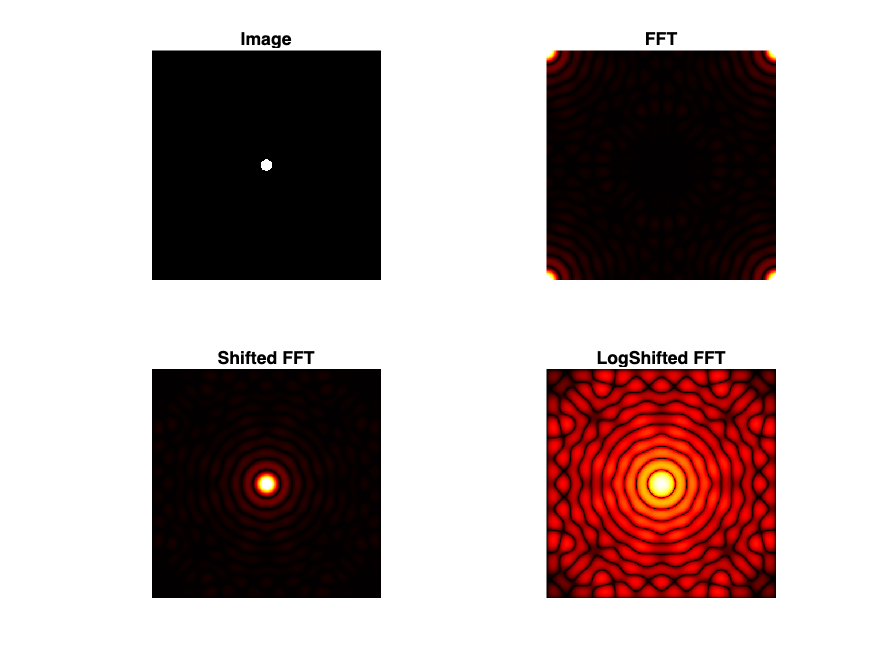

Fourier_transform(GraphCircle(0.01));

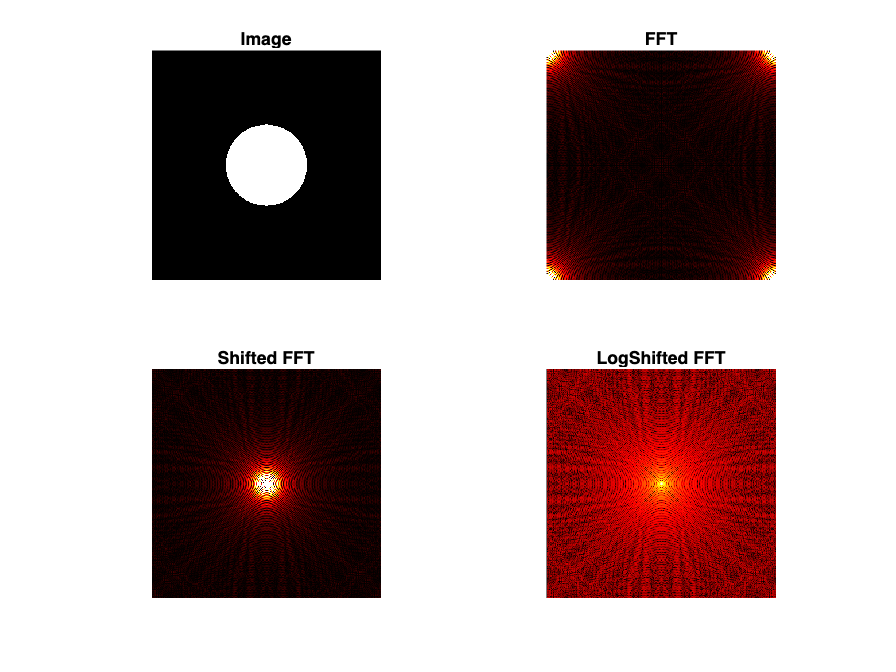

Fourier_transform(GraphCircle(0.5));

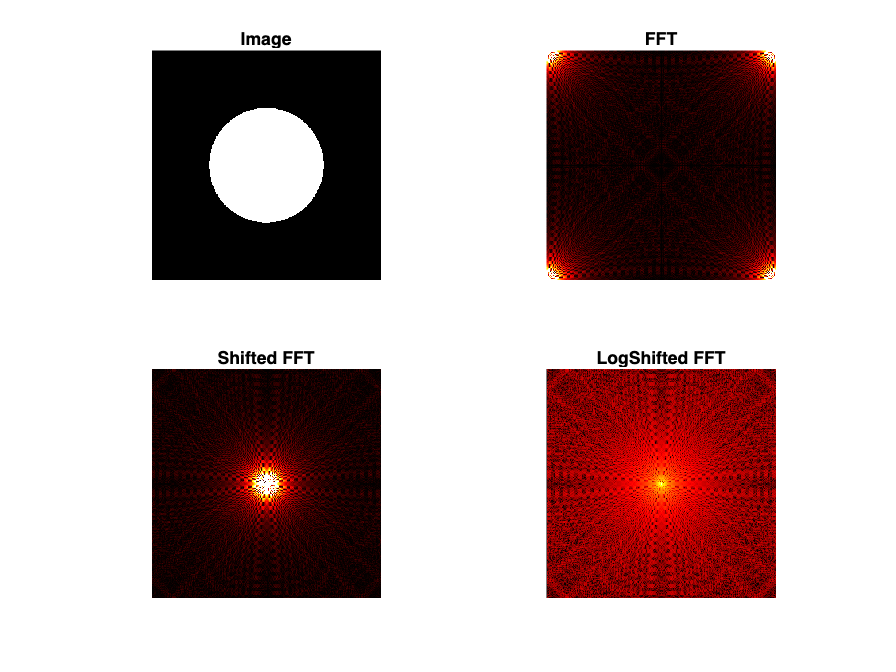

Fourier_transform(GraphCircle(1));

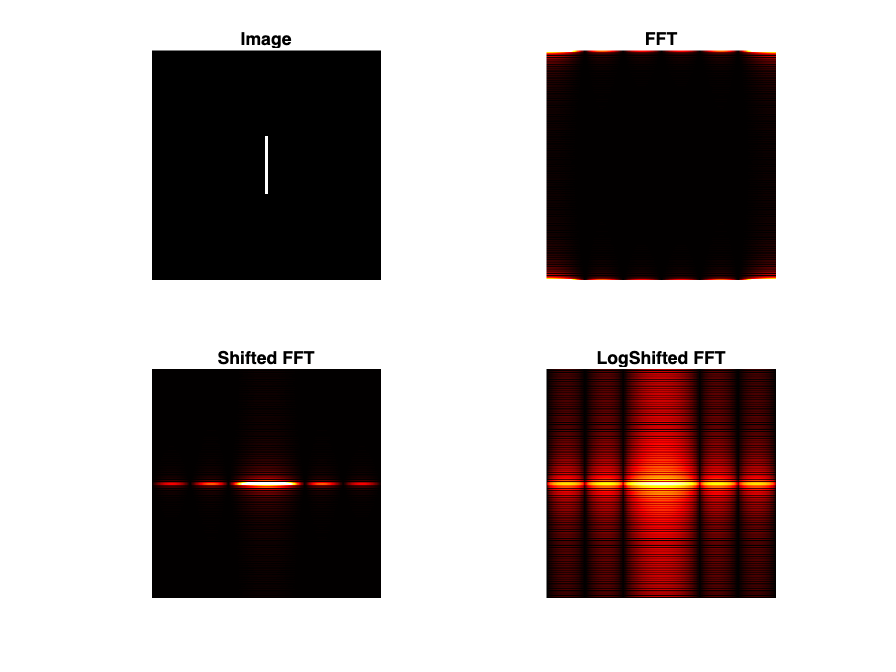

Fourier_transform(single_slit(5));

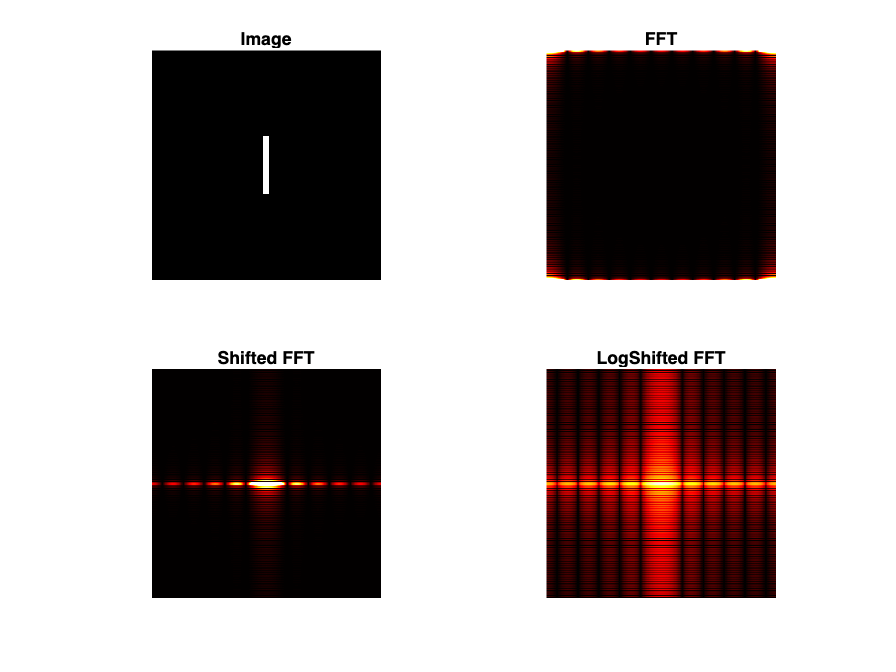

Fourier_transform(single_slit(10));

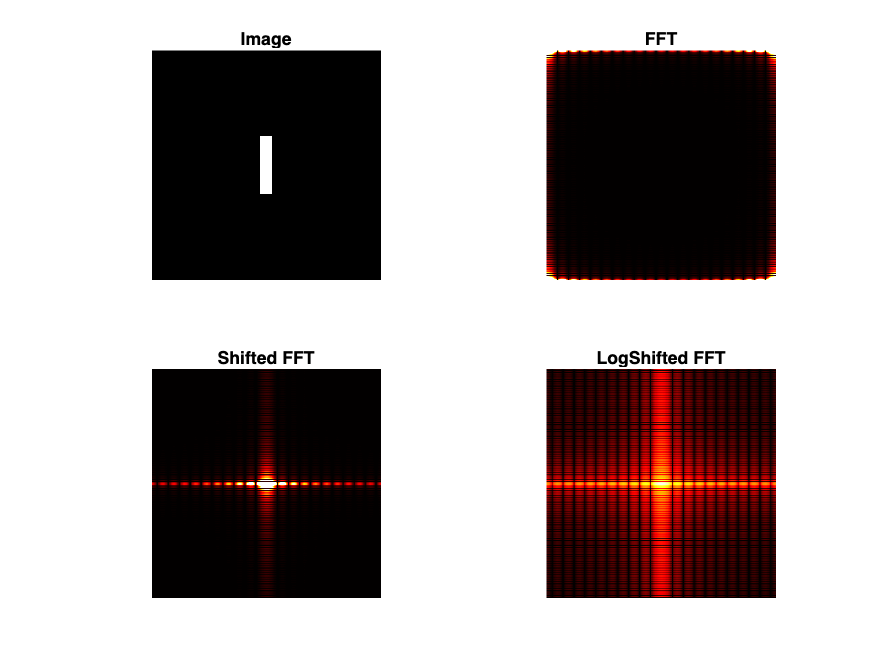

Fourier_transform(single_slit(20));

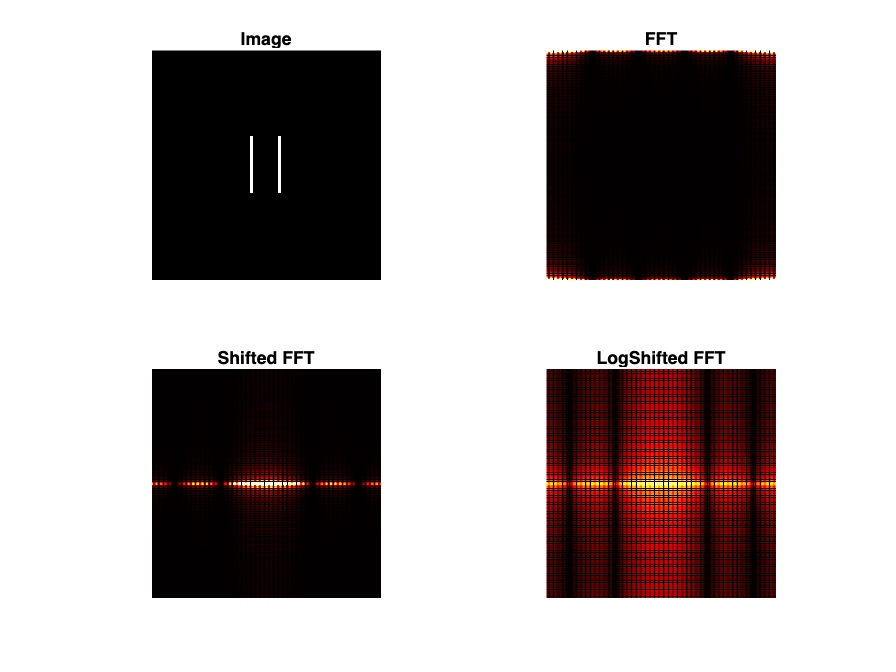

Fourier_transform(doubleSlitImage1(5));

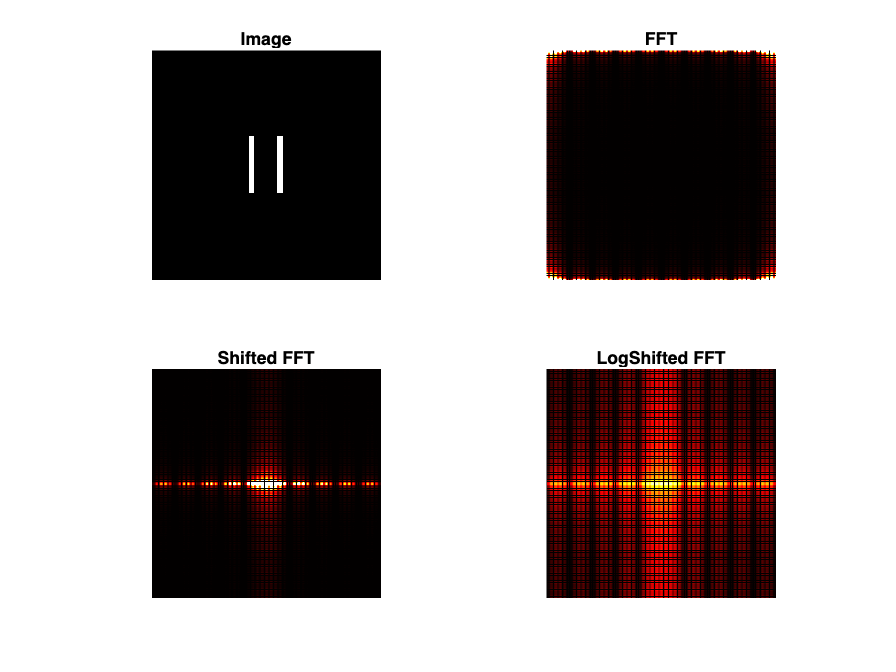

Fourier_transform(doubleSlitImage1(10));

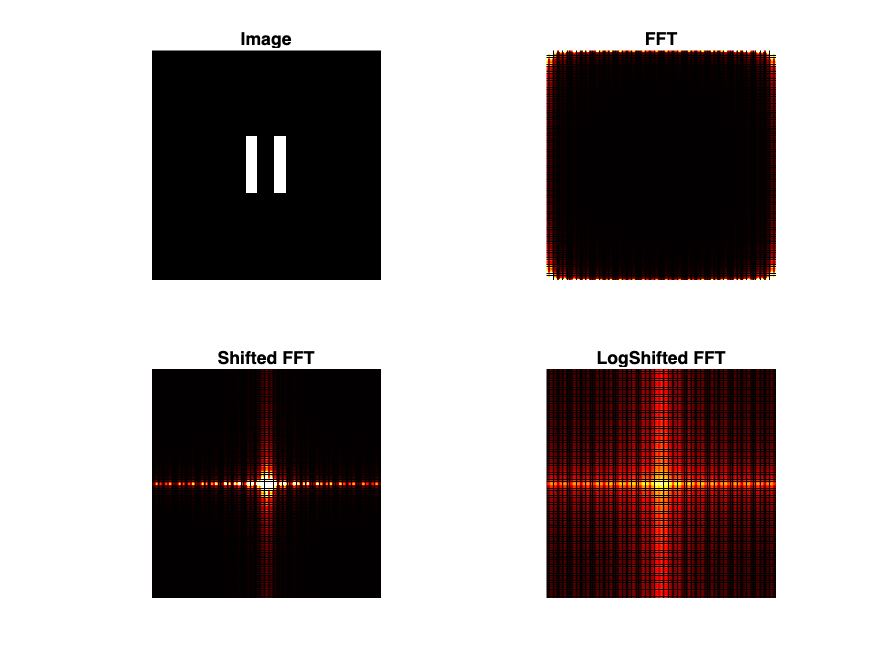

Fourier_transform(doubleSlitImage1(20));

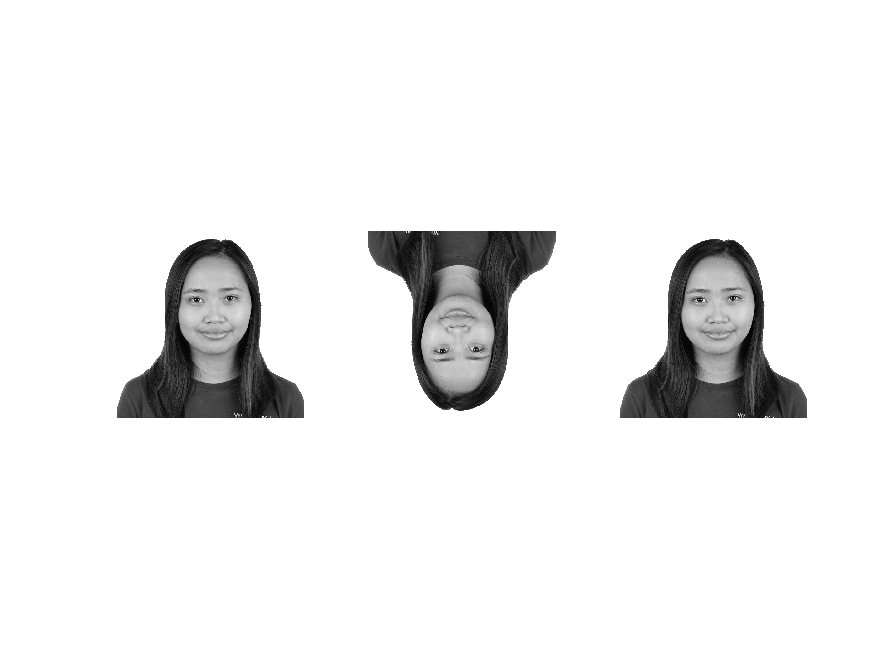

I = rgb2gray(imread('IDPic.jpg'));
figure();
subplot(1,3,1);
imshow(I);
Irec = fft2 (fft2(I));
subplot(1,3,2);
imagesc(abs(Irec));
colormap gray;
axis off;
axis image;
Irec2 = ifft2(fft2(I));
subplot(1,3,3);
imagesc(abs(Irec2)); 
colormap gray;
axis image;
axis off;

## Activity 2.2 Simulation of an imaging system 

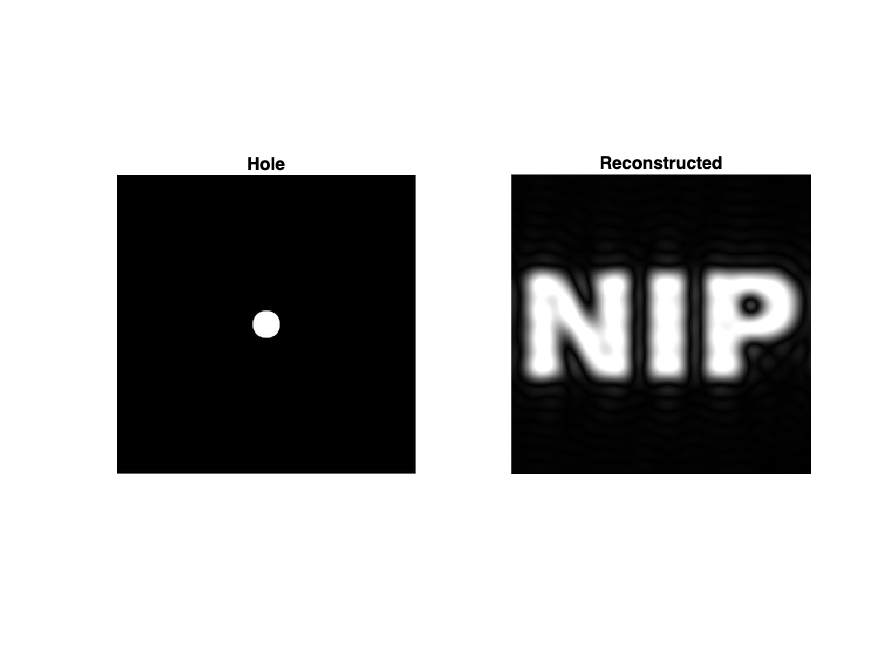

Convolution('1.png');

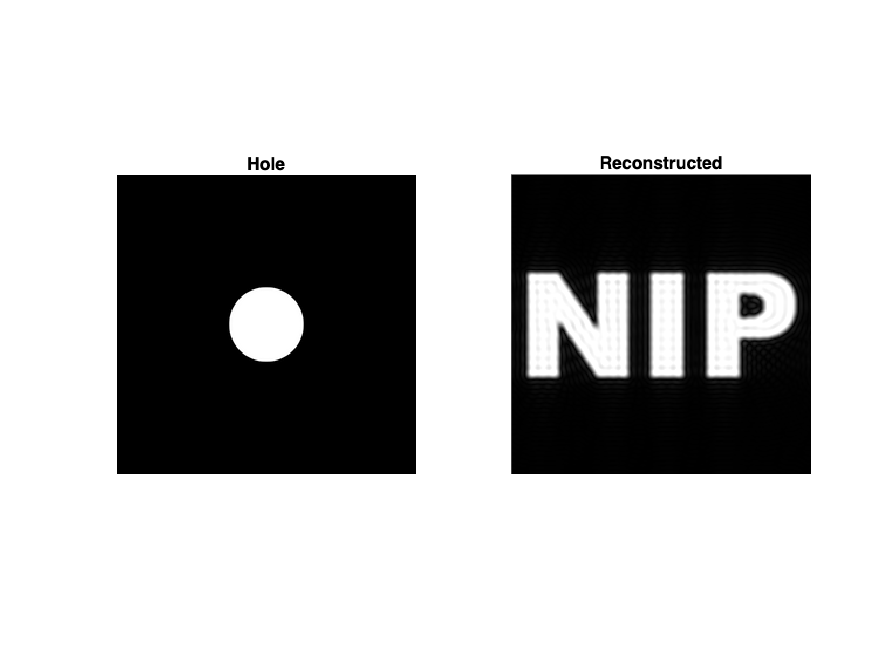

Convolution('2.png');

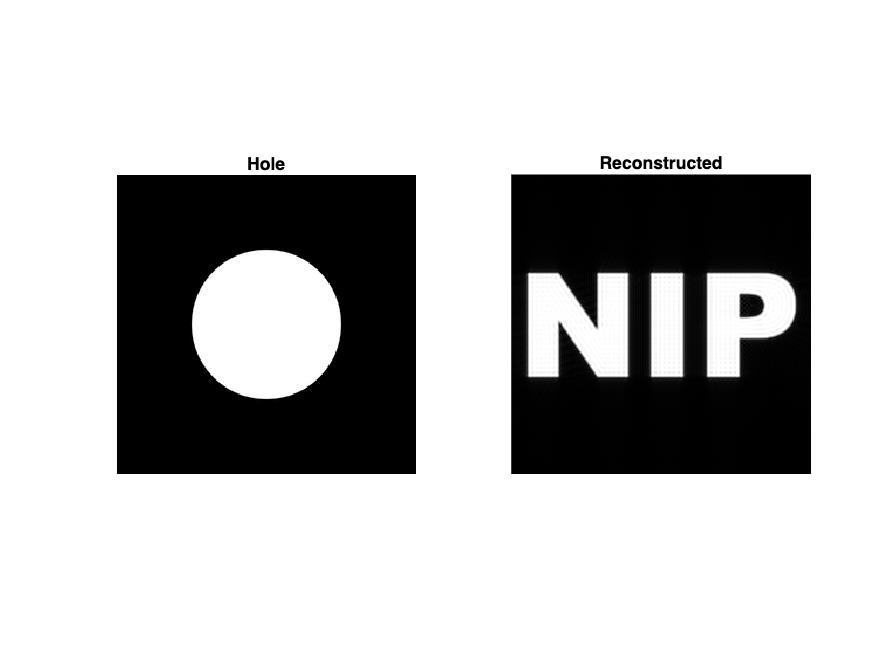

Convolution('3.png');

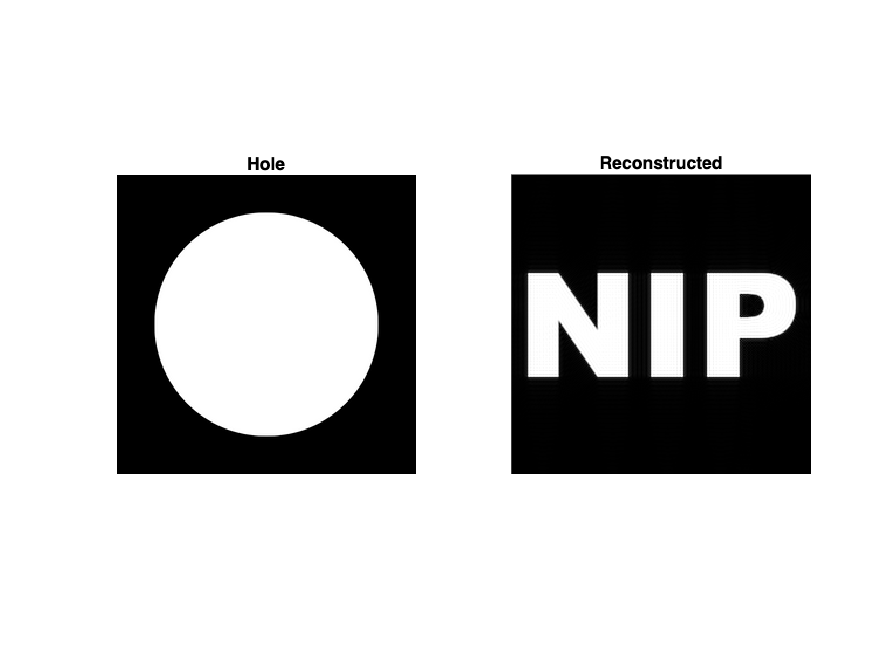

Convolution('4.png');

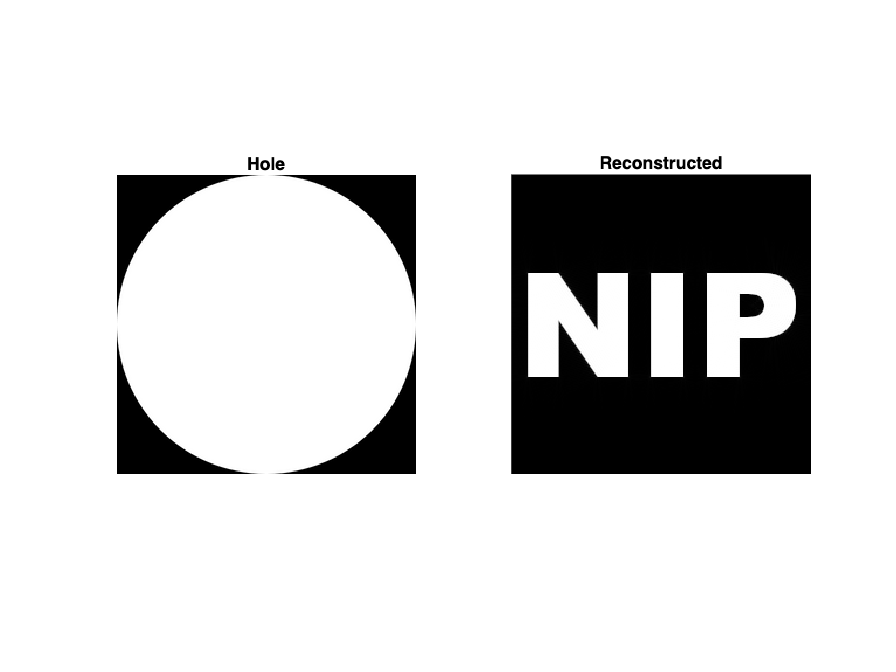

Convolution('5.png');

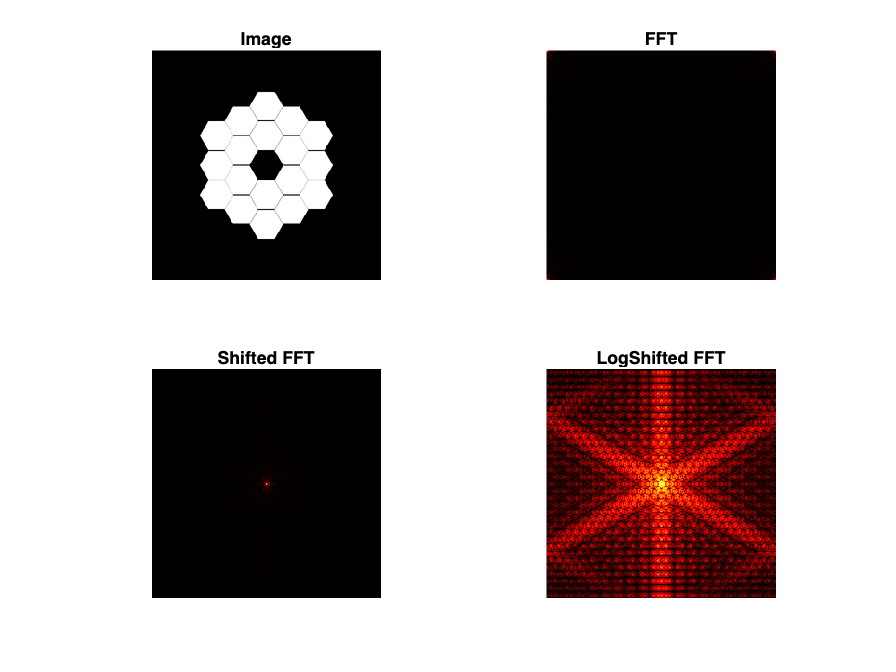

JWST('JWST Primary Mirror.png');

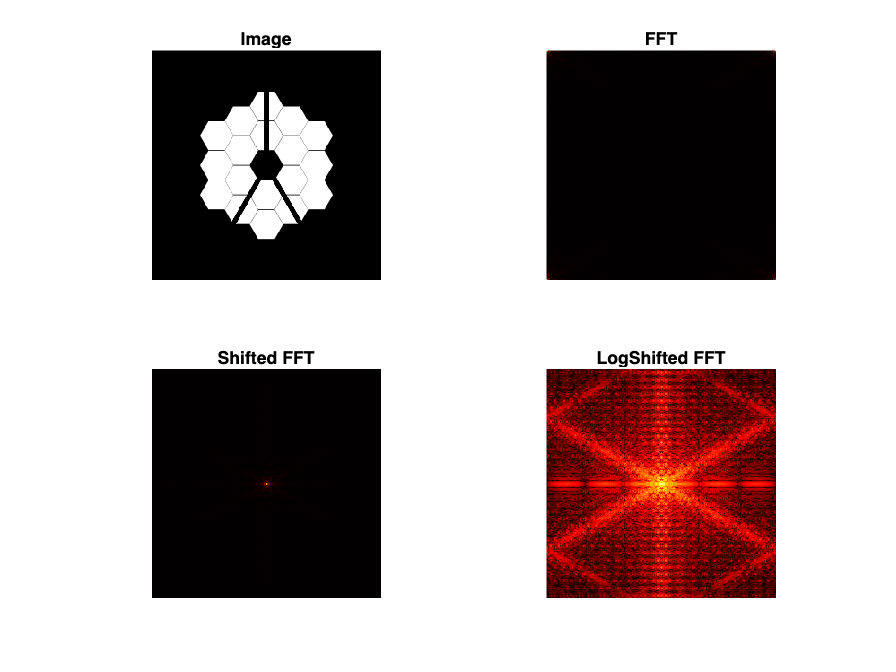

JWST('JWST Primary Mirror2.png');

## Activity 2.3 Correlation

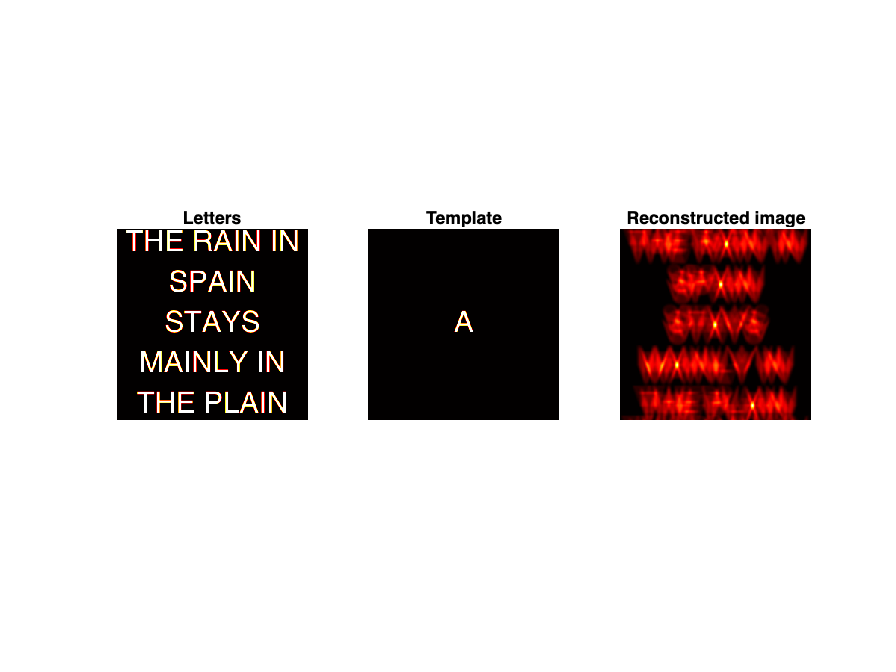

correlation('a.png');

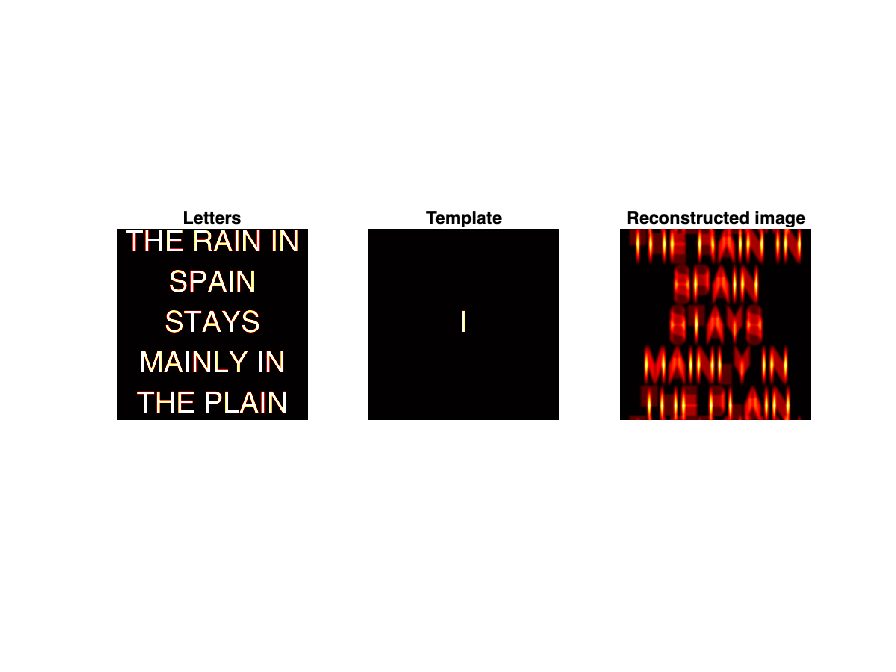

correlation('i.png');

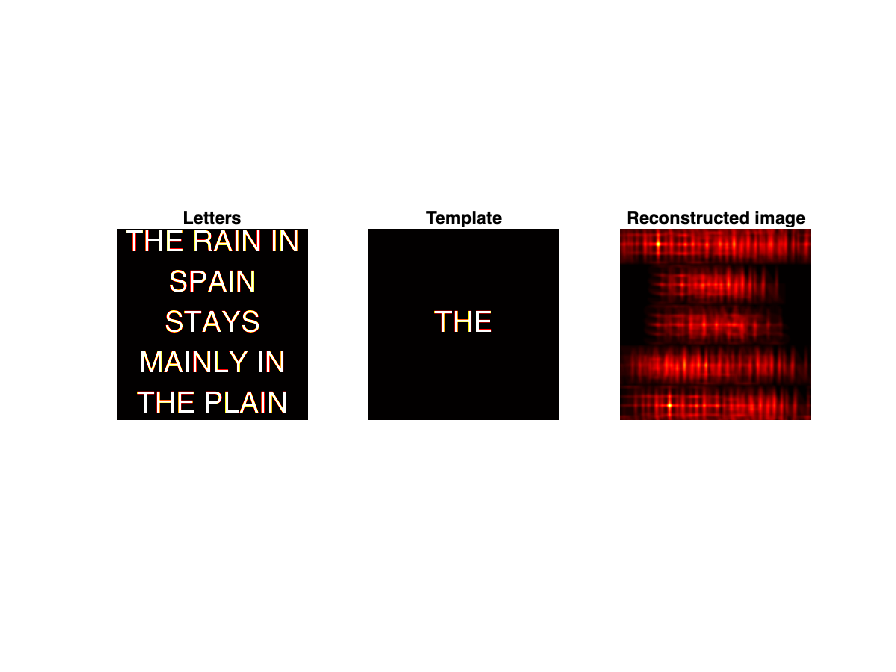

correlation('the.png');

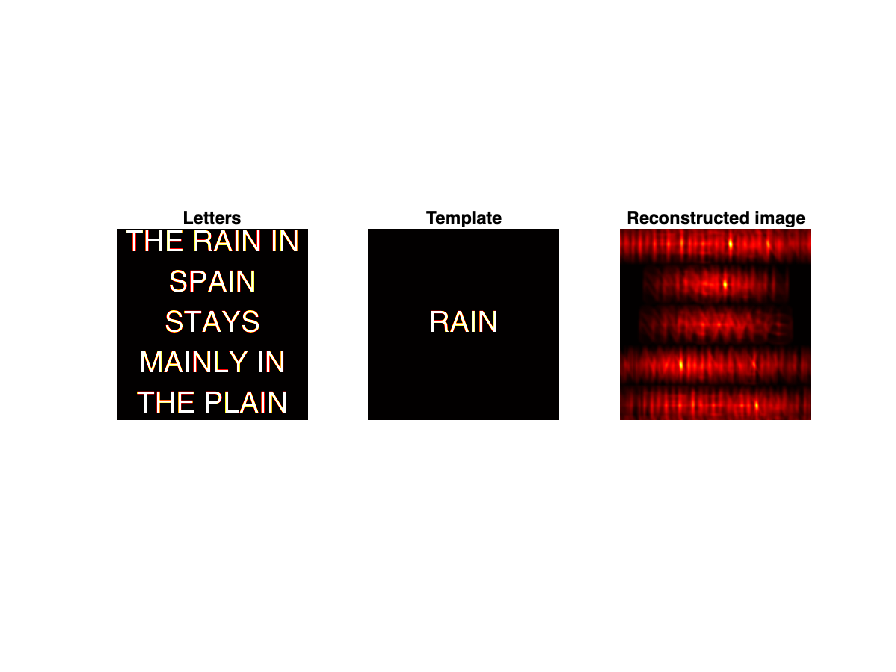

correlation('rain.png');

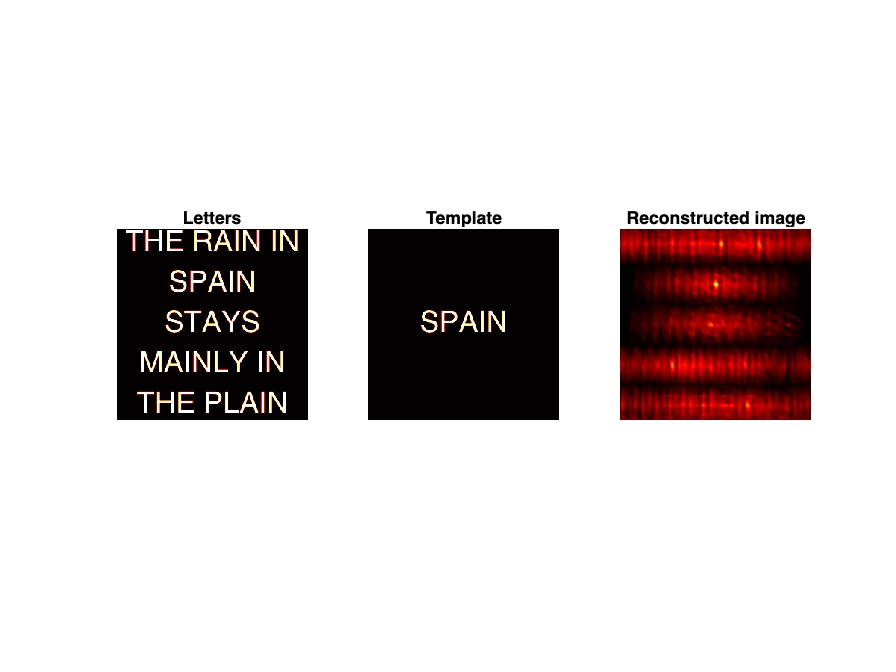

correlation('spain.png');

## The functions used above are created in the lines below: 

function Fourier_transform(apperture)
    Fourier_transform = fft2(apperture);
    Fourier_Mag = abs(Fourier_transform);
    shifted_Fourier_transform = fftshift(Fourier_transform);
    mag_shift_FourierT = abs(shifted_Fourier_transform);
    log_mag_shift_FT = rescale(log(mag_shift_FourierT+1),0,256);
    fig = figure;
    img1 = Fourier_Mag;
    img2 = mag_shift_FourierT;
    img3 = log_mag_shift_FT;
    im = apperture;
    colormap('hot');
    subplot(2,2,1);
    im = imshow(apperture);
    title('Image');
    
    subplot(2,2,2);
    image(img1);
    axis off;
    axis image; 
    title('FFT');
    
    subplot(2,2,3);
    image(img2);
    axis off;
    axis image;
    title('Shifted FFT');
    
    subplot(2,2,4);
    image(img3);
    axis off;
    axis image; 
    title('LogShifted FFT');
end


function slit_image = single_slit(d)

% Create an L x L matrix of zeros
slit_image = zeros(400, 400);

% Calculate the x-coordinates of the slit
x = [200 - d/2, 200 + d/2];

% Loop through the x-coordinates of the slit
for i = round(x(1)) : round(x(2))
    
    % Loop through the y-coordinates of the slit
    for j = round(200 - 100/2) : round(200 + 100/2)
        
        % Set the pixels within the central region to 1
        if i >= round(x(1) + (x(2) - x(1) - d)/2) && i <= round(x(1) + (x(2) - x(1) + d)/2)
            slit_image(j, i) = 1;
        end
    end
end
end



function image = doubleSlitImage1(slitWidth)
    % create a blank image with the specified dimensions
    image = zeros(400, 400);
    
    % calculate the x-coordinate ranges of the slits
    slit1Left = floor(175  - slitWidth/2);
    slit1Right = slit1Left + slitWidth - 1;
    slit2Left = floor(225 - slitWidth/2);
    slit2Right = slit2Left + slitWidth - 1;
    
    % set the values in the image corresponding to the slits
    for i = 1:400
        if i >= slit1Left && i <= slit1Right
            startRow = floor(150);
            endRow = startRow + 100 - 1;
            image(startRow:endRow, i) = 1;
        end
        if i >= slit2Left && i <= slit2Right
            startRow = floor(150);
            endRow = startRow + 100 - 1;
            image(startRow:endRow, i) = 1;
        end
    end
end

function Convolution(hole)
    A = imread(hole);
    A = im2double(A);
    Ashift = fftshift(A);
    Image = imread('NIP_letter.tiff');
    Image = im2double(Image);
    FImage = fft2(Image(:,:,1));
    H = Ashift .* FImage;
    h = ifft2(H);
    subplot(1,2,1); image(A); axis off ; axis image; title('Hole');
    subplot(1,2,2); imagesc(abs(h));colormap gray; axis image; axis off; title('Reconstructed')
end


function JWST(pic)
    A = rgb2gray(im2double(imread(pic)));
    Fourier_transform = fft2(A);
    Fourier_Mag = abs(Fourier_transform);
    shifted_Fourier_transform = fftshift(Fourier_transform);
    mag_shift_FourierT = abs(shifted_Fourier_transform);
    log_mag_shift_FT = rescale(log(mag_shift_FourierT+1),0,256);
    fig = figure;
    img1 = Fourier_Mag;
    img2 = mag_shift_FourierT;
    img3 = log_mag_shift_FT ;
    im = pic;
    subplot(2,2,1);
    im = imshow(pic);
    title('Image');
    
    subplot(2,2,2);
    imagesc(img1);
    colormap hot;
    axis off;
    axis image; 
    title('FFT');
    
    subplot(2,2,3);
    imagesc(img2);
    colormap hot;
    axis off;
    axis image;
    title('Shifted FFT');

    subplot(2,2,4);
    imagesc(img3);
    axis off;
    axis image; 
    title('LogShifted FFT');
end


function [a,b,c] = correlation(letter)
    I = im2gray(imread('text.png'));    
    A = im2gray(imread(letter));
    Afft2 = fft2(A);
    Ifft2 = fft2(I);
    P = conj(Afft2) .* Ifft2 ;
    smallp = ifft2(P);
    reconstruction = fftshift(abs(smallp));
    a = subplot(1,3,1); image(I); axis image; axis off; title('Letters');
    b = subplot(1,3,2); image(A); axis image; axis off; title('Template');
    c= subplot(1,3,3); imagesc(reconstruction); axis image; axis off; title('Reconstructed image');
end

function A = GraphCircle(r)
    N = 400;
    x = linspace(-2,2,N);
    y = x;
    [X,Y] = meshgrid(x,y);
    R = (X.^2 + Y.^2);
    A = zeros(size(R));
    A(R<r) = 1;
end
